# Axis Control

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

gasprices = readtable("./data/gasprices.csv", "Range", "A5:K24");

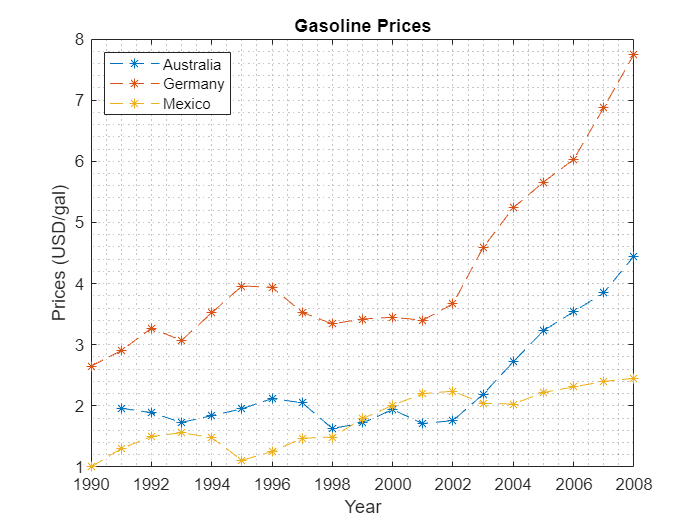

Year = gasprices.Year;
Australia = gasprices.Australia;
Germany = gasprices.Germany;
Mexico = gasprices.Mexico;

plot(Year, Australia, "*--")
hold on
grid minor
plot(Year, Germany, "*--")
plot(Year, Mexico, "*--")
hold off
xlabel("Year")
ylabel("Prices (USD/gal)")
t = "Gasoline Prices";
title(t)
legend("Australia", "Germany", "Mexico", "Location", "northwest")

## Task 1

Before looking at the data from the 1990's separately from the 2000's, let's extract the default limits of the graph.

You can use the function `axis` with no inputs to get the current axes limits. For example, if the following figure is open:

then the command `v` `=` `axis` returns a vector of 4 elements containing the *x*- and *y*-axis limits.

`v` `=` `axis`

 `v` `=` 

      `10`   `20`   `1`   `5`

xyLims = axis

xyLims =         1990        2008           1           8


## Task 2

You can use the functions `xlim` and `ylim` to set the *x*- and *y*-axis limits. Both functions take a vector of two elements as an input. For example, the following command sets the lower *y*-axis limit to 2 and the upper *y*-axis limit to 4.

`ylim``([``2` `4``])`

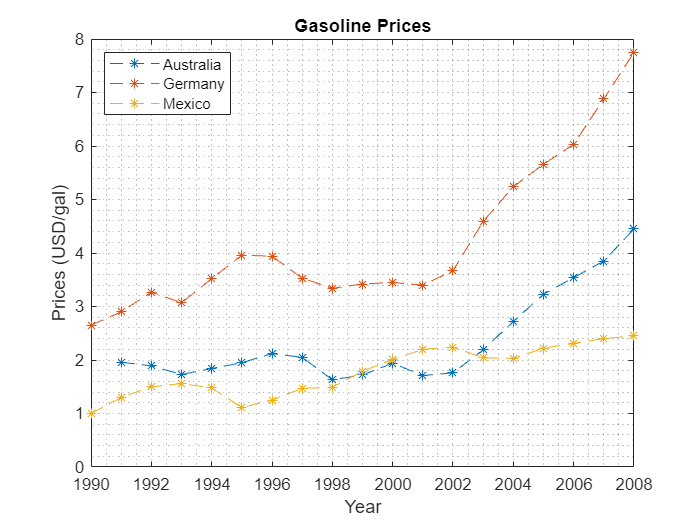

ylim([0 xyLims(end)])

## Task 3

To focus on the steady increase that started around 2001, you need to change the *x*- axis limits to start at 2001 and go to the final year, which is stored in the second element of `xyLims`.

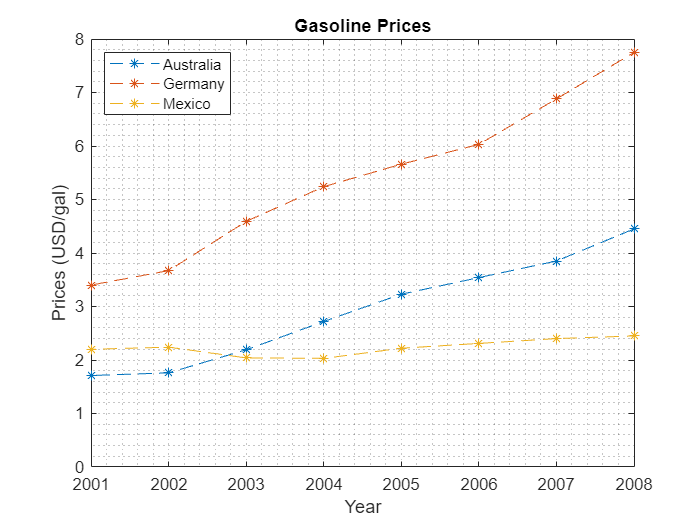

xlim([2001 xyLims(2)])

## Task 4

When you change the *x*- and *y*-axis limits, the underlying data in the axes is not modified—it's all still there. Only the way the plot is displayed is changed.

If you want to change the axes limits to equal exactly the range of the data, use the command:

`axis` `tight`

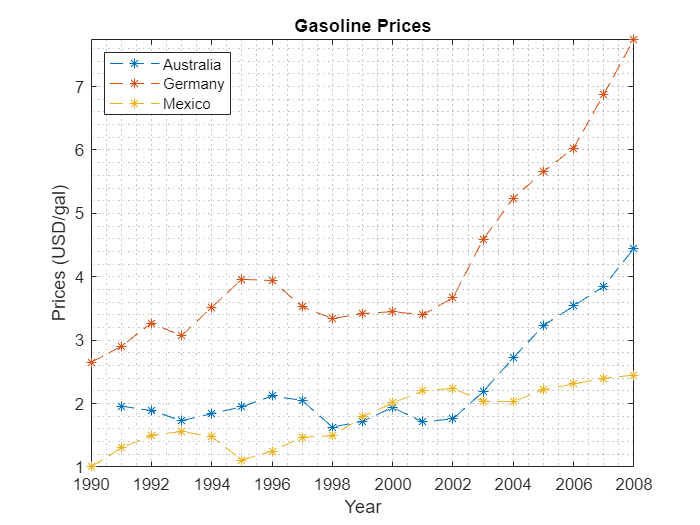

axis tight